% lb = [-5 3];
% ub = [1.03 3.1];
% ndec = 2; % so chu so thap phan
% numTotal = (ub'-lb')/10^(-ndec) + 1;
% n = floor(log2(numTotal)) + 1;
% len = sum(n);
% popSize = 50;
% 
% pop = rand(popSize, len);
% pop(pop>0.5) = 1;
% pop(pop<0.5) = 0;
% pop
% cl = [1; cumsum(n(1:end-1)+1)];
% cu = cumsum(n);
% floatNum = zeros(popSize, length(n));
% % vars = cell(length(n),1);
% for i=1:length(n)
%     tmp = pop(:,cl(i):cu(i));
%     tmp2(:,i) = bi2de(tmp,2,'left-msb');
% %     gene encoding, with lb = lower bound, ub = upper bound
% %     X = X_lb + bin2dec(Xbin)*(X_ub-X_lb)/(2^bitlength-1)
%     floatNum(:,i) = lb(i) + bi2de(tmp,2,'left-msb') ...
%         *(ub(i)-lb(i))/(2^(n(i))-1);
% end
% floatNum
% % binNum = zeros(popSize,len);

% cumsum(n(1:end-1))+1

% % clear tmp
% for i=1:length(n)
%     binNum(:,cl(i):cu(i)) = de2bi(round((floatNum(:,i)-lb(i))*(2^(n(i))-1)/(ub(i)-lb(i))),'left-msb');
% end
% all(pop==binNum,'all')

load COMTraj.mat
maxGens = 10;
probCrossover = 1;
probMutation = 0.003;
useClamping=1; useSigmaScaling=1; useSUS=1; crossoverType=3; useMaskRepositories=1; ... % set additional functions 
flagFreq=0.01;unflagFreq=0.01;flagPeriod=200;... % clamping parameters
sigmaScalingCoeff=1;... % sigma scaling parameters
maskReposFactor=5;... % mask repositories parameters
% lb=[0 7*pi/4 5*pi/4 0 -250 -212 -290 -200];
% ub=[1e-3 2*pi 2*pi pi 250 212 290 200];
lb = [-100 -100 -100 -100 0];
ub = [100 100 100 100 20];
COMxmax=300;ndec=2;... % constraints
Len1=50; Len2=400; Len3=400; h1=20;
l1=25; l2=200; l3=200; l4=300;
m1=1; m2=5; m3=6; m4=20; ... % exoskeleton parameters
COMRef=[-xCOM+0.17 yCOM]*1e3; tf=1;... % input parameters
t1i = 0;
postureInit = [0 0 -pi/2 pi/2
                0 0 0 0
                0 0 0 0];
postureEnd = [0 0 0 0
              0 0 0 0];

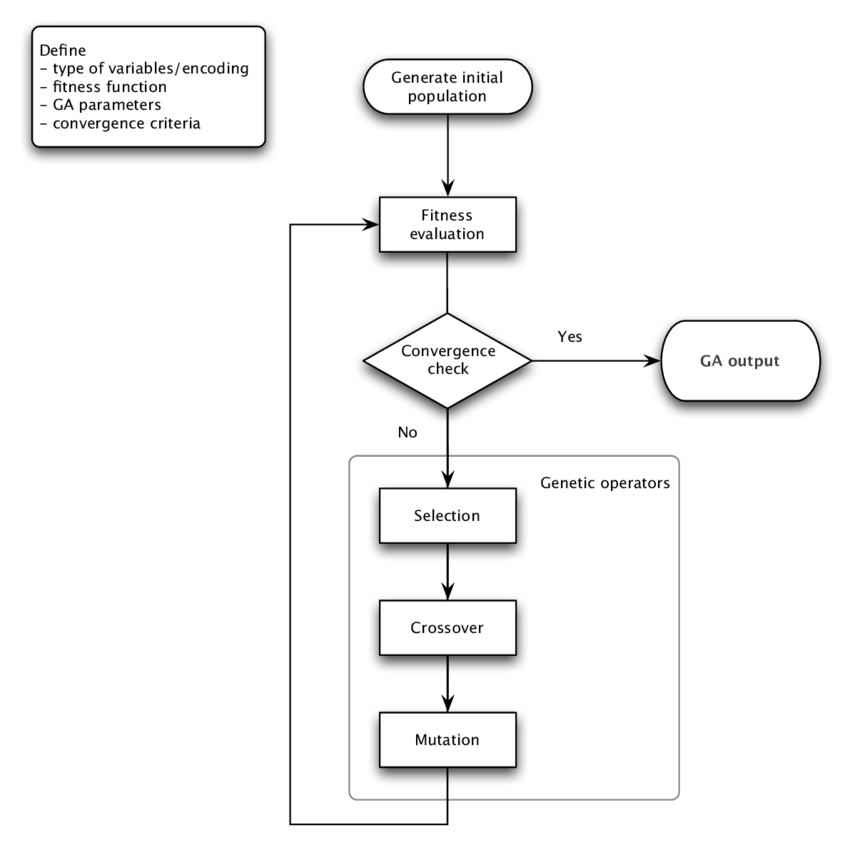

% generate initial population
numTotal = (ub'-lb')/10^(-ndec) + 1;
n = floor(log2(numTotal)) + 1;
numVars = length(n);
len = sum(n);
cl = [1; cumsum(n(1:end-1))+1];
cu = cumsum(n);

% generate time variable
nt = size(COMRef,1);

% generate population size based on the number of
% referenced COM
popSize = 200;

% preallocate vectors for recording the average and maximum fitness in each
% generation
avgFitnessHist=zeros(1,maxGens+1);
maxFitnessHist=zeros(1,maxGens+1);
eliteIndiv=[];
eliteFitness=-realmax;

% clamping parameters
if useClamping
    flaggedGens=-ones(1,len);
else
    flaggedGens=0;
end

% crossover masks to use if crossoverType==1.
if crossoverType==1
    mutationOnlycrossmasks=false(popSize,len);
else
    mutationOnlycrossmasks=0;
end

% pre-generate two “repositories” of random binary digits from which the  
% the masks used in mutation and uniform crossover will be picked. 
% maskReposFactor determines the size of these repositories.
if useMaskRepositories
    uniformCrossmaskRepos = rand(popSize/2,(len+1)*maskReposFactor) < 0.5;
    mutmaskRepos = rand(popSize,(len+1)*maskReposFactor) < probMutation;
else
    uniformCrossmaskRepos = 0;
    mutmaskRepos = 0;
end

% the population is a popSize by len matrix of randomly generated real
% decimal values. The values are bounded according to conditions.
decPop = zeros(popSize,numVars);
binPop = zeros(popSize,len);
for i=1:numVars
    decPop(:,i) = lb(i) + rand(popSize,1)*(ub(i)-lb(i));
end

for gen=0:maxGens
    
    thetas = decPop(:,1:numVars/2);
    taus = decPop(:,numVars/2+1:end);
        
    % FITNESS EVALUATION                   
    fitnessVals = GAFitnessFunc(Len1,Len2,Len3,h1,...
                       l1,l2,l3,l4,...
                       m1,m2,m3,m4,...
                       lb,ub,COMxmax,tfmin,... % constraints
                       COMRef,thetas,taus,tf,popSize)';
    
    %% RECORD THE BEST CANDIDATE
    [avgFitnessHist, maxFitnessHist, eliteFitness, eliteIndiv] = ...
        GAEliteCandidate(decPop, fitnessVals, gen, ...
            avgFitnessHist, maxFitnessHist, eliteFitness, eliteIndiv);
    
    %% ENCODING
    binPop = GAEncoding(binPop,decPop,n,numVars,lb,ub,cl,cu);
    
    %% SELECTION
    [firstParents,secondParents] = GASelection(binPop, fitnessVals, popSize, ...
    useSigmaScaling, sigmaScalingCoeff, useSUS);
    
    %% CROSSOVER
    binPop = GACrossover(firstParents,secondParents,popSize,len,probCrossover,... standard crossover parameters
            crossoverType,useMaskRepositories,mutationOnlycrossmasks,maskReposFactor,uniformCrossmaskRepos);
    
    %% MUTATION
    binPop = GAMutation(binPop, popSize, len, probMutation, ...
            useMaskRepositories, maskReposFactor, mutmaskRepos, ...
            useClamping, flagFreq, unflagFreq, flagPeriod, flaggedGens);
    
    %% DECODING
    decPop = GADecoding(binPop,decPop,n,numVars,lb,ub,cl,cu);
end

% repmat(lb,popSize,1) < [thetas taus]
% repmat(lb,numVars,1)
binPop

binPop = 596×89 logical array
   1   1   1   1   1   1   0   1   1   1   1   1   1   0   0   1   1   0   0   0   0   1   0   0   0   0   1   0   1   1   1   0   0   1   1   0   1   0   1   1   1   0   1   0   0   1   0   1   1   1
   1   1   1   1   0   1   0   0   1   1   0   1   1   0   1   1   1   0   0   0   0   1   1   0   0   0   0   1   1   0   0   0   0   0   0   1   1   0   1   1   0   0   1   0   0   1   1   1   0   0
   1   1   1   1   1   1   0   0   1   1   0   1   0   1   1   1   1   1   1   0   0   0   1   1   0   1   1   0   1   1   0   1   0   0   1   1   0   0   1   0   0   0   0   0   0   0   1   1   1   0
   0   1   1   1   1   1   0   0   1   1   0   0   1   1   1   0   1   1   0   0   0   0   1   1   0   1   0   1   1   1   1   0   0   1   1   1   1   0   1   1   0   1   1   0   1   1   0   1   0   1
   0   0   0   0   0   1   0   1   1   1   0   0   0   1   0   0   1   1   1   0   0   1   1   0   1   0   0   0   1   0   1   1   0   1   1   1   0   1   1   0   1  